# Laboratorio di Automatica (prova del 31 Gennaio 2020)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

January 31, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 3

Sia 


$$P(s)\,=\, \frac{Y(s)}{U_a(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


la funzione di trasferimento di un motore elettrico in corrente continua, da ingresso in tensione di armatura $u_a$ in $[V]$ ad uscita in *posizione* $y$ in $\mathrm{[rad]}$. Si supponga di controllare la posizione del motore con uno schema di controllo in catena chiusa a tempo discreto del tipo mostrato in Fig. 1. 

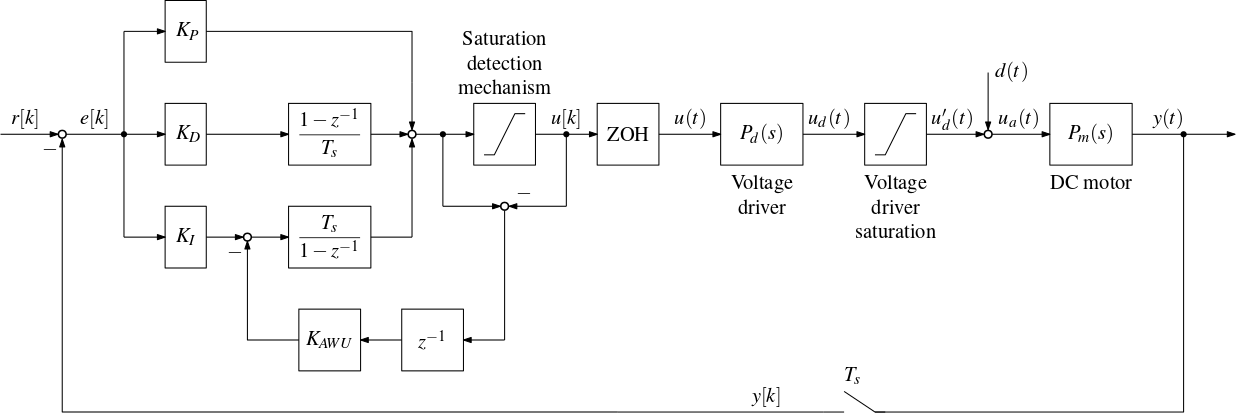

**Figura 1:** Sistema di controllo di posizione a tempo discreto.

Il controllore è la versione discretizzata, con il metodo di Eulero all'indietro (backward Euler - BE), di un controllore PID a tempo continuo con guadagni:


$$K_P = 15\,,\quad 
K_I = 280\,,\quad
K_D = 0.21$$


Il controllore include uno schema di anti-windup (AWU) dell'integratore. Lo schema AWU comprende un blocco di saturazione con livelli di saturazione pari a $\pm 6\,\mathrm{V}$, e un guadagno $K_{AWU}=50$. Il motore è comandato con un driver in tensione la cui funzione di trasferimento da ingresso $u(t)$(comando in tensione) ad uscita $u_d$ (tensione di uscita non saturata) è assimilabile a quella di un puro ritardo temporale $T_d$, cioè:


$$P(s) = \frac{U_D(s)}{U(s)} = e^{-sT_d}
\qquad\text{con}\qquad
T_d = 10\,\mathrm{ms}
$$


All'uscita $u_d$ del driver è presente una saturazione, con livelli di saturazione pari a $\pm 6\,\mathrm{V}$.

Considerando un tempo di campionamento pari a $T_s = 5\,ms$, si svolgano i seguenti punti:

1) Realizzare uno schema Simulink del sistema di controllo di posizione a tempo discreto illustrato in Fig. 1. 

*Note*: 

- per simulare il blocco con funzione di trasferimento $P_d(s)$(ritardo temporale), si faccia ricorso al blocco `Continuous `$\rightarrow$` Trasnsport Delay` della libreria di blocchi del Simulink.

- per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco `Discrete `$\rightarrow$` Zero-Order Hold` della libreria di blocchi del Simulink.

*Soluzione*.

%   sampling time
Ts = 5e-3;

%   continuous-time plant tf
Tm = 0.03;
km = 5.2;
sysP = tf(km, [Tm, 1, 0]);

%   actuation time-delay
Td = 10e-3;

%   PID controller gains 
kp = 15;
ki = 280;
kd = 0.21;

%   anti-windup gain
kawu = 0;

%    open Simulink model
open_system('ex3_sim1');

2) Assumendo inizialmente $K_{AWU}=0$ (schema AWU disattivato), simulare la risposta del sistema di controllo ad un riferimento di posizione $r$ a gradino di ampiezza pari a $A_r=1\,\mathrm{rad}$, applicato all'istante $t_{0,r} = 0.1\,s$. Si esegua la simulazione su un intervallo temporale di $1.5\,s$. Mostrare poi in una figura MATLAB gli andamenti dei seguenti segnali:

- *plot 1:* posizione $y[k]$ e riferimento $r[k]$, entrambi espressi in $[\mathrm{rad}]$.

- *plot 2*: segnale di comando $u[k]$, espresso in $[V]$.

*Soluzione*.

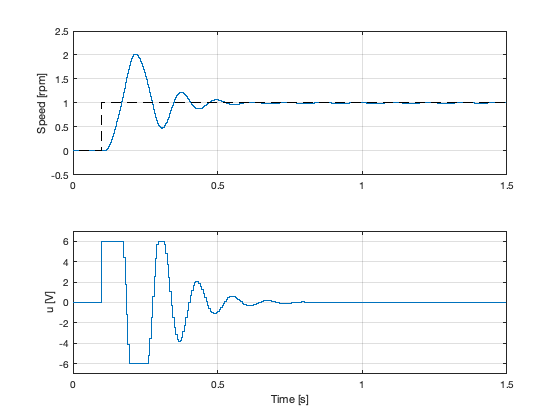

%    set reference params (amplitude & start time)
Ar = 1;  t0r = 0.1;  

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.001', 'StopTime','1.5');

%    run simulation
sim('ex3_sim1');

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
u = simres.signals(2).values(:,1);

%   plot results
figure;
subplot(2,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylabel('Speed [rpm]');
grid on;

subplot(2,1,2);
stairs(t, u);
ylabel('u [V]');
xlabel('Time [s]');
grid on;
ylim([-7,7]);

3) Ripetere il punto 2, assumendo $K_{AWU}=50$.

*Soluzione*.

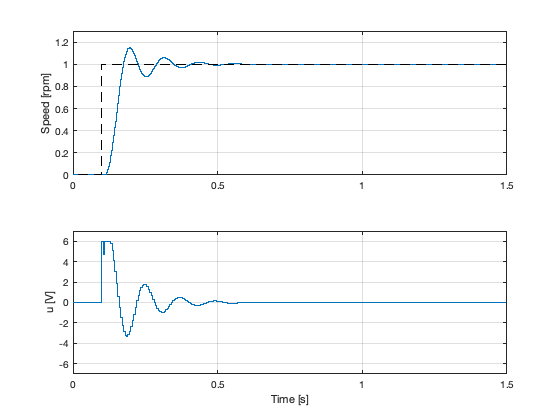

%   anti-windup gain
kawu = 50;

%    run simulation
sim('ex3_sim1');

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
u = simres.signals(2).values(:,1);

%   plot results
figure;
subplot(2,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylabel('Speed [rpm]');
grid on;
ylim([0,1.3]);

subplot(2,1,2);
stairs(t, u);
ylabel('u [V]');
xlabel('Time [s]');
grid on;
ylim([-7,7]);